# random test for wrtieAnt

## add test for readAnt

       32767



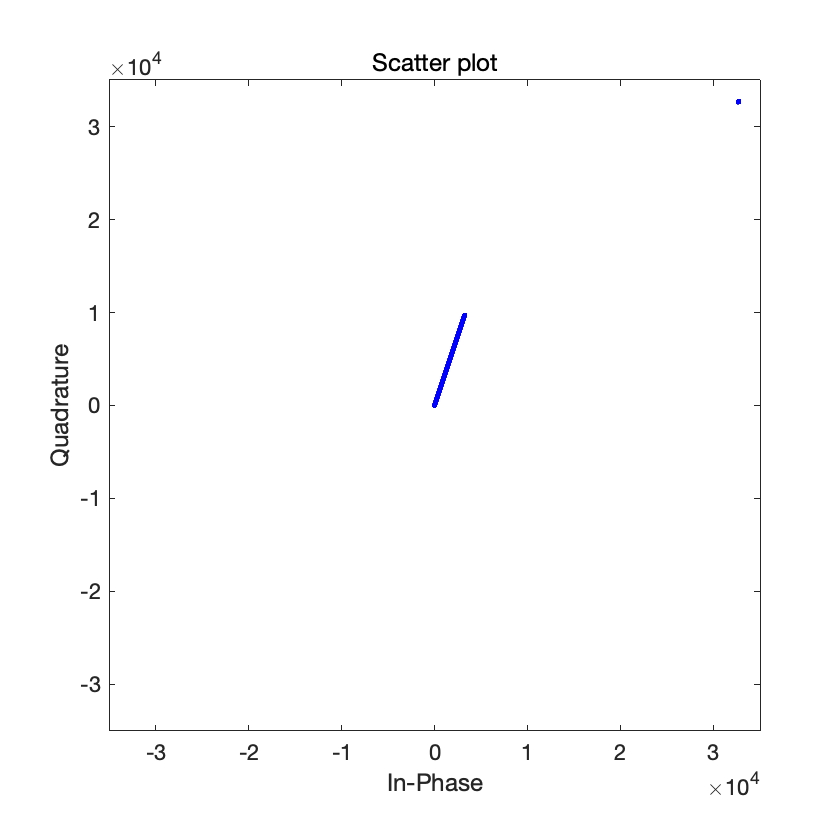

clc;
clear;
testfile='good.bin';
randtest=0;

if randtest==1
    a=rand(1,3276*14);
    a_fft=fft(a);
    a0=ifft(a_fft);
    
    a_iq(:,1)=real(a_fft);
    a_iq(:,2)=imag(a_fft);
    a_iq1=reshape(a_iq',1,length(a_iq)*2)';
    data=writeAnt_fixed(testfile,a_iq1);
    data1=readAnt(testfile);
    data2=reshape(data1',1,length(a_iq))';
    pos=real(data2)==(2^15-1);
    data2(pos)=2^15+1i*imag(data2(pos));
    data3=ifft(data2);
else
    a=1:3276*14*20;
    a_iq(:,1)=mod(a,(2^15));
    a_iq(:,2)=mod(3*a,(2^15));
    a_iq1=reshape(a_iq',1,length(a_iq)*2)';
    data=writeAnt(testfile,a_iq1);
    data1=readAnt(testfile);
    data2=reshape(data1,length(a_iq),1);
end



disp('ok!');

ok!


fprintf("Data length is %d",length(data2));

Data length is 917280